# wdwStockman

**Deriving the cone fundamentals: a subspace intersection method - Figure 1**

Comparing whether the W. D. Wright color matching functions (CMFs) are within a linear transform of the Stockman cone fundamentals.

In part, this tests reduction dichromacy. But mainly, we test whether the WDW data, collected about 70 years ago, can be directly compared with modern international standards.

The data from different time periods are stored at different wavelength samples, so we keep reading in the Stockman in order to match the wavelength sampling.

See also

- wdwDataProtanDeutan.m - Tables of the data that we copied in and then wrote out into the data directory.

## Protanope CMF

fname = fullfile(iefundamentalsRootPath,'data','wdw','cmfProtan.mat');
load(fname,'wave','cmfProtan');
stockman = ieReadSpectra('stockmanEnergy',wave);

To check the linear transformation, we simply solve (for example

 protan = stockman*L

Lprotan = stockman\cmfProtan;
estProtan = stockman*Lprotan;

ieNewGraphWin([],'big');
pColor = [1 1 1]*0;
tiledlayout(2,2);

nexttile;
plot(wave(1:2:end),estProtan(1:2:end,:),'ko','Linewidth',1,'MarkerSize',2);
hold on; plot(wave,cmfProtan,'-','Color',pColor,'Linewidth',2);
set(gca,'xtick',400:100:700,'ytick',0:0.5:1,'xlim',[400 700],'ylim',[-0.2 1.2]);
grid on;

% {
% If you want a label, ....
 title('Protan');
 xlabel('Wavelength (nm)');
 ylabel('Primary intensity (a.u.)'); grid on;
%}


## Deutan

fname = fullfile(iefundamentalsRootPath,'data','wdw','cmfDeutan.mat');
load(fname,'wave','cmfDeutan');

nexttile;
Ldeutan = stockman\cmfDeutan;
estDeutan = stockman*Ldeutan;
plot(wave(1:2:end),estDeutan(1:2:end,:),'ko','Linewidth',1,'MarkerSize',2);
hold on;
plot(wave,cmfDeutan,'-','Color',pColor,'Linewidth',2)
grid on;
set(gca,'xtick',400:100:700,'ytick',0:0.5:1,'xlim',[400 700],'ylim',[-0.2 1.2]);



## Tritan -  measured wavelengths differ

% Also, the stored data are not scaled to 1.  We do the scaling here.
fname = fullfile(iefundamentalsRootPath,'data','wdw','cmfTritan.mat');
load(fname,'obsAverage');

wave = min(obsAverage.wave):max(obsAverage.wave);
cmfTritan = interp1(obsAverage.wave,obsAverage.CMF,wave);
stockman = ieReadSpectra('stockmanEnergy',wave);

nexttile;
% We scale because it was not scaled to 1 in the original
cmfTritan = ieScale(cmfTritan,1);
Ltritan = stockman\cmfTritan; 
estTritan = stockman*Ltritan; 
plot(wave(1:2:end),estTritan(1:2:end,:),'ko', 'LineWidth',1,'MarkerSize',2);
hold on; plot(wave,cmfTritan,'-','Color',pColor,'Linewidth',2)
grid on;
set(gca,'xtick',400:100:700,'ytick',0:0.5:1,'xlim',[400 700],'ylim',[-0.2 1.2]);


## DeutanC - back to original wave

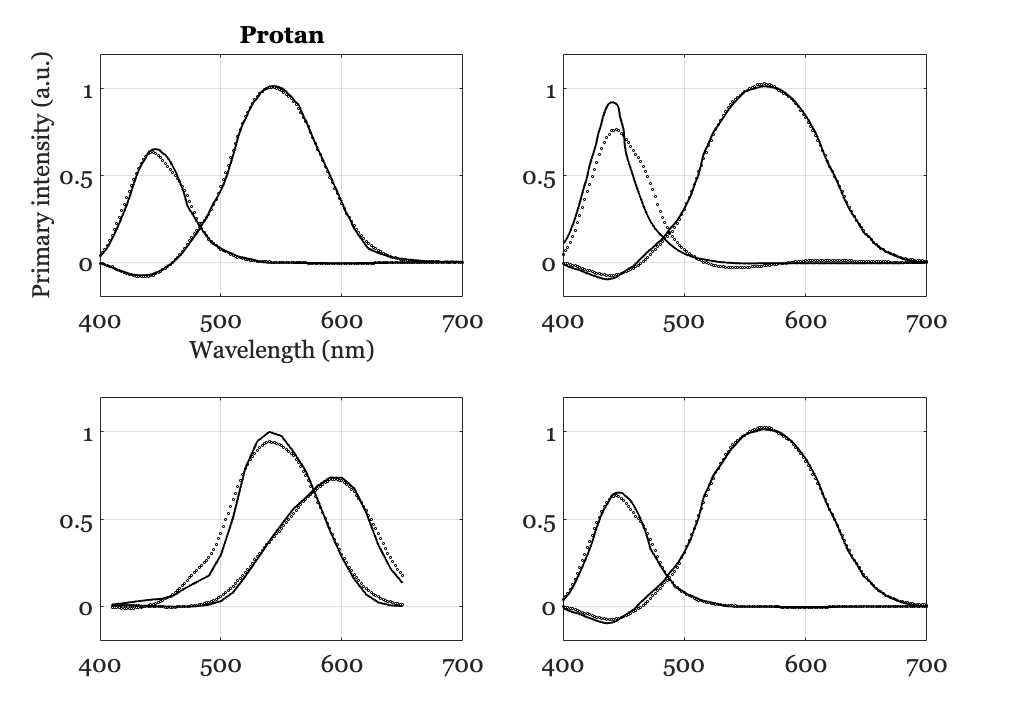

fname = fullfile(iefundamentalsRootPath,'data','wdw','cmfDeutanC.mat');
load(fname,'wave','cmfDeutanC');
stockman = ieReadSpectra('stockmanEnergy',wave);

nexttile;
LdeutanC = stockman\cmfDeutanC;
estDeutanC = stockman*LdeutanC;
plot(wave(1:2:end),estDeutanC(1:2:end,:),'ko','Linewidth',1,'MarkerSize',2);
hold on;
plot(wave,cmfDeutanC,'-','Color',pColor,'Linewidth',2)
grid on;
set(gca,'xtick',400:100:700,'ytick',0:0.5:1,'xlim',[400 700],'ylim',[-0.2 1.2]);

fontsize(gcf,24,'points');